# FUNCTION FOR GETTING Zw

function Zw = get_phase(obj_images, ref_images, x, y, l, w, freq, rotation_angle)

## Import and convert object images to grayscale and rotate

    I1o = imrotate(im2gray(imread(obj_images{1})), rotation_angle);
    I2o = imrotate(im2gray(imread(obj_images{2})), rotation_angle);
    I3o = imrotate(im2gray(imread(obj_images{3})), rotation_angle);
    I4o = imrotate(im2gray(imread(obj_images{4})), rotation_angle);

## Import and convert reference images to grayscale and rotate

    I1 = imrotate(im2gray(imread(ref_images{1})), rotation_angle);
    I2 = imrotate(im2gray(imread(ref_images{2})), rotation_angle);
    I3 = imrotate(im2gray(imread(ref_images{3})), rotation_angle);
    I4 = imrotate(im2gray(imread(ref_images{4})), rotation_angle);

## Crop images

    rect = [x, y, l, w];
    I1o = imcrop(I1o, rect);
    I2o = imcrop(I2o, rect);
    I3o = imcrop(I3o, rect);
    I4o = imcrop(I4o, rect);

    I1 = imcrop(I1, rect);
    I2 = imcrop(I2, rect);
    I3 = imcrop(I3, rect);
    I4 = imcrop(I4, rect);

    % Convert images to double precision arrays
    I1o = double(I1o);
    I2o = double(I2o);
    I3o = double(I3o);
    I4o = double(I4o);

    I1 = double(I1);
    I2 = double(I2);
    I3 = double(I3);
    I4 = double(I4);

## Calculate wrapped phase for object and background

    wrapped_object = atan2((I4o-I2o), (I1o-I3o));
    wrapped_bg = atan2((I4-I2), (I1-I3));

    figure(1); imagesc(wrapped_object);
    figure(2); imagesc(wrapped_bg);

## Unwrap phase 

    uo = unwrap_TIE_FFT_DCT(wrapped_object);
    ub = unwrap_TIE_FFT_DCT(wrapped_bg) ;

    %uo = unwrap(wrapped_object, [], 2);
    %ub = unwrap(wrapped_bg, [], 2);

    figure(3);imagesc(uo);
    figure(4); imagesc(ub);

## Plot the unwrapped phase as a 3D surface

    [X, Y] = meshgrid(1:size(uo, 2), 1:size(uo, 1));
    figure(5);
    mesh(X, Y, uo);
    title('3D Plot of Unwrapped Phase');
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Unwrapped Phase');
    colormap(gca, gray);

## Plot the unwrapped phase as a 3D surface

    [X, Y] = meshgrid(1:size(ub, 2), 1:size(ub, 1));
    figure(6);
    mesh(X, Y, ub);
    title('3D Plot of Reference Unwrapped Phase');
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Unwrapped Phase');
    colormap(gca, gray);

Reference

se = strel('disk', 15);
background = imopen(uo, se);
imagesc(background);

## Phase to height

    L = 65;
    p = freq;
    d = 26;
    phi = uo - background;
    figure(7); surf(phi);
    
    Zw = (L * p * phi) ./ ((2 * pi * (d)) + (p * phi));

## Plot height map of Zw

    figure(8);
    surf(Zw);
    title('Height Map of Zw');
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Height (Zw)');
    zlim([-2 2]);

end

## ACTUAL CODE HERE

% Object images
obj_images_0 = {"0Ao.JPG", "0Bo.JPG", "0Co.JPG", "0Do.JPG"};
obj_images_2 = {"2Ao.JPG", "2Bo.JPG", "2Co.JPG", "2Do.JPG"};
obj_images_3 = {"3Ao.JPG", "3Bo.JPG", "3Co.JPG", "3Do.JPG"};
obj_images_5 = {"5Ao.JPG", "5Bo.JPG", "5Co.JPG", "5Do.JPG"};

% Reference images
ref_images_0 = {"0A.jpg", "0B.JPG", "0C.JPG", "0D.JPG"};
ref_images_2 = {"2A.JPG", "2B.JPG", "2C.JPG", "2D.JPG"};
ref_images_3 = {"3A.JPG", "3B.JPG", "3C.JPG", "3D.JPG"};
ref_images_5 = {"5A.JPG", "5B.JPG", "5C.JPG", "5D.JPG"};

## Cropping images

x_0 = 2000;
y_0 = 650;
l_0 = 650;
w_0 = 980;

x_2 = 2100; % X top left
y_2 = 1200; % Y top left
l_2 = 300;  % Width 
w_2 = 300;  % Height

x_3 = 2100; % X top left
y_3 = 1200; % Y top left
l_3 = 300;  % Width 
w_3 = 300;  % Height

x_5 = 2070; % X top left
y_5 = 1600; % Y top left
l_5 = 400;  % Width 
w_5 = 300;  % Height

## Use function

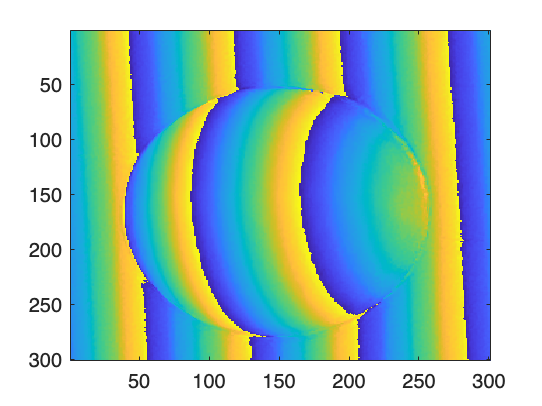

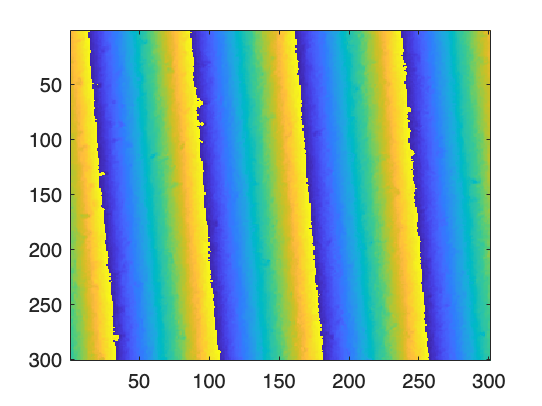

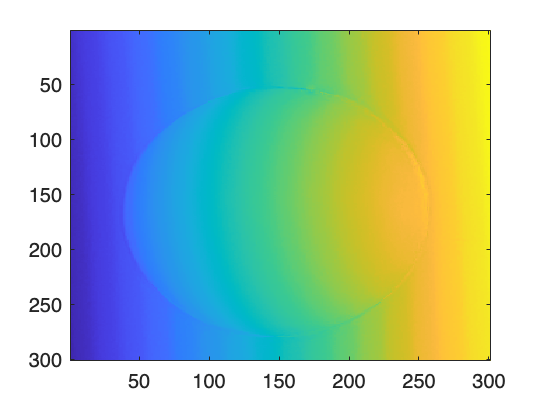

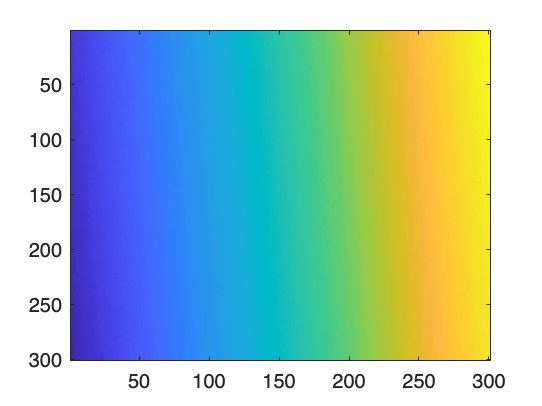

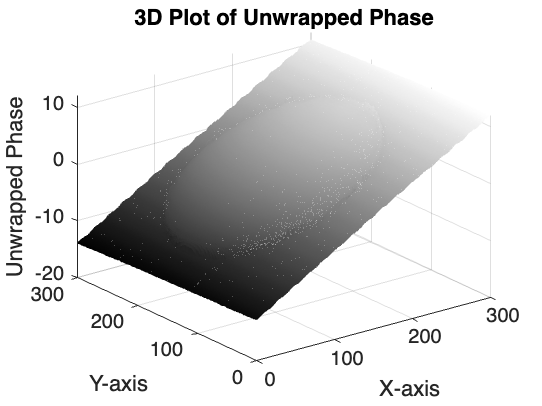

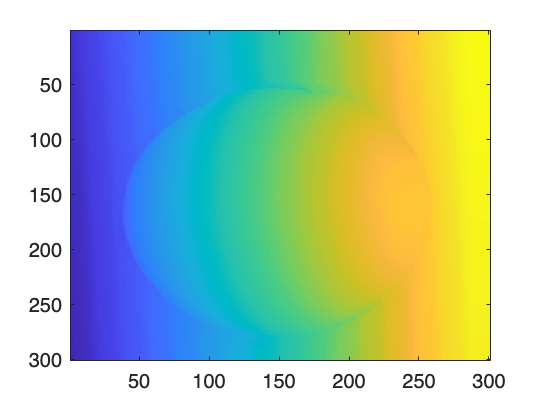

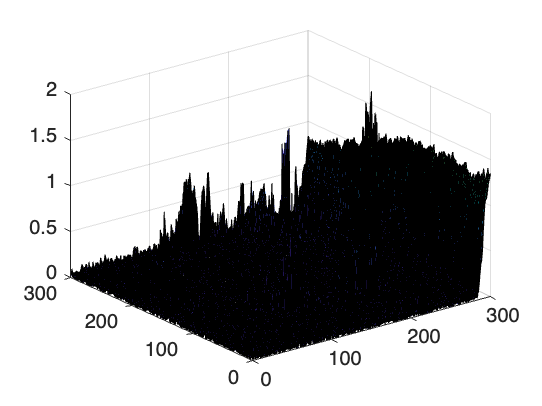

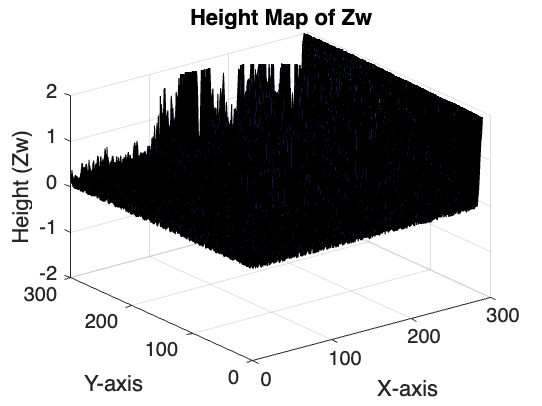

%Zw_0 = get_phase(obj_images_0, ref_images_0, x_0, y_0, l_0, w_0, 50, 0);
%Zw_2 = get_phase(obj_images_2, ref_images_2, x_2, y_2, l_2, w_2, 50, 0);
Zw_3 = get_phase(obj_images_3, ref_images_3, x_3, y_3, l_3, w_3, 10, 0);

%Zw_5 = get_phase(obj_images_5, ref_images_5, x_5, y_5, l_5, w_5, 50, 0);